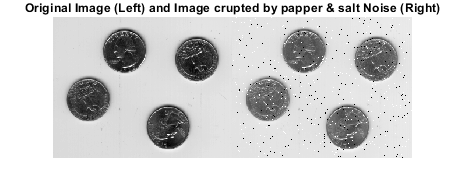

clc; clear; close;
I = imread('eight.tif');
J = imnoise(I,'salt & pepper',0.02);
figure; imshowpair(I,J,'montage'); colormap;
title('Original Image (Left) and Image crupted by papper & salt Noise (Right)');

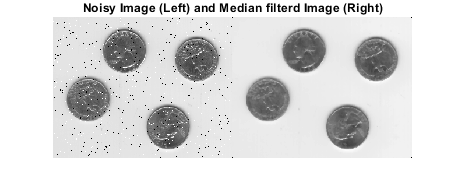

K = medfilt2(J);
figure; imshowpair(J,K,'montage'); colormap;
title('Noisy Image (Left) and Median filterd Image (Right)');

2)  Generate the basis functions of 2-D DCT.

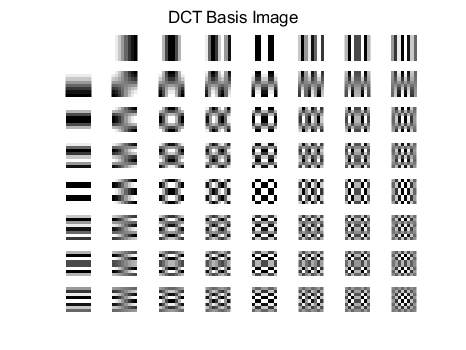

M=8; N=8; [m,n]=meshgrid(0:M-1,0:N-1);
figure;  sgtitle('DCT Basis Image')
for k1=1:M
    for k2=1:N
        k=k1-1; l=k2-1;
%         B=cos((2*m+1)*k*pi/(2*M))*cos((2*n+1)*l*pi/(2*N));
        B=cos(((2*m+1)*k*pi)/(2*M)).*cos(((2*n+1)*l*pi)/(2*N));
        subplot(M,N,M*(k2-1)+k1);
        imshow(B,[]);
    end
end

3)  Consider a 1-D sequencex`(`n`)`of lengthN,

(i) Find the even symmetrical DCT

(ii) Reconstructx`(`n`)`using inverse even symmetrical DCT

(iii) Compare the results with MATLAB functionsdctandidct.

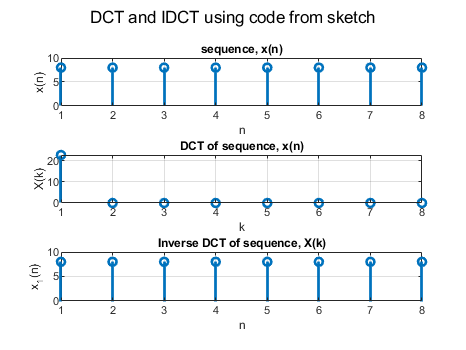

N= 8; %input('Enter the length of sequence = ')
% xn = randi(100,1,N);
xn=[8 8 8 8 8 8 8 8];
for k=1:N
    if k==1
        alpha(k)=1/sqrt(N);
    else
        alpha(k)=2/sqrt(N);
    end
        for n=1:N
        coff(n)=xn(n)*cos(((2*(n-1)+1)*pi*(k-1))/(2*N));
        end
        y(k)=alpha(k)*sum(coff);
end
% z=[y(end:-1:1) y(2:end)]
for n=1:N
    for k=1:N
        if k==1
        alpha(k)=1/sqrt(N);
        else
        alpha(k)=2/sqrt(N);
        end
        coff(k)=alpha(k)*y(k)*cos(((2*(n-1)+1)*pi*(k-1))/(2*N));
    end
    xn1(n)=sum(coff);
end

figure; sgtitle('DCT and IDCT using code from sketch')
subplot(311); stem(xn,'linewidth',2); grid; 
title('sequence, x(n)'); xlabel('n'); ylabel('x(n)');
subplot(312); stem(y,'linewidth',2); grid;
title('DCT of sequence, x(n)'); xlabel('k'); ylabel('X(k)');
subplot(313); stem(xn1,'linewidth',2); grid;
title('Inverse DCT of sequence, X(k)'); xlabel('n'); ylabel('x_1(n)');

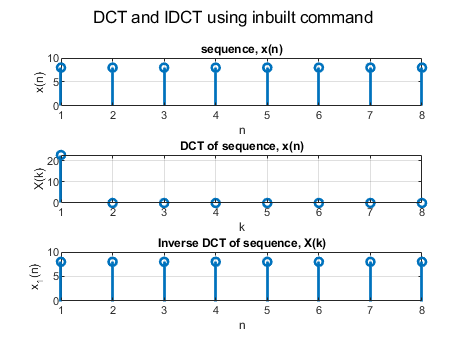

% Using dct and idct inbuilt command 
figure; sgtitle('DCT and IDCT using inbuilt command')
subplot(311); stem(xn,'linewidth',2); grid;
title('sequence, x(n)'); xlabel('n'); ylabel('x(n)')
subplot(312); stem(dct(xn),'linewidth',2); grid;
title('DCT of sequence, x(n)'); xlabel('k'); ylabel('X(k)')
subplot(313); stem(idct(y),'linewidth',2); grid;
title('Inverse DCT of sequence, X(k)'); xlabel('n'); ylabel('x_1(n)');

4)  Consider an image of sizeN`1×`N`2`, 

(i) Find the DCT coefficients of the image

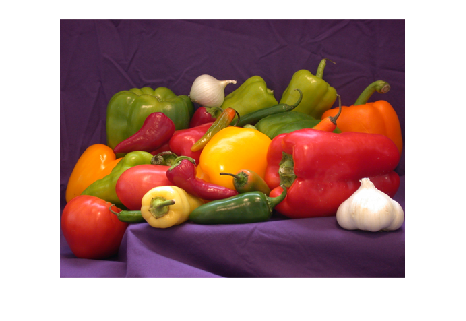

I = imread('peppers.png'); figure; imshow(I);

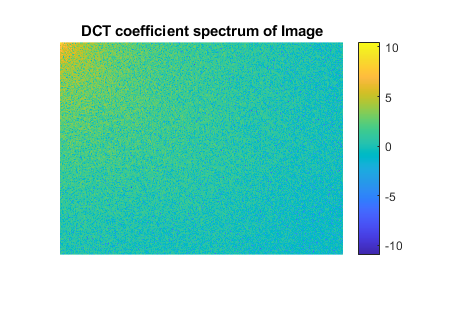

I = im2gray(I);
J = dct2(I);
figure; imshow(log(abs(J)),[]); colormap parula; colorbar
title('DCT coefficient spectrum of Image')

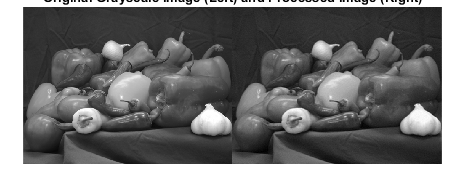

J(abs(J) < 10) = 0;
K = rescale(idct2(J));
figure; montage({I,K})
title('Original Grayscale Image (Left) and Processed Image (Right)');

(ii) Reconstruct the image with various number of significant and insignificant coefficients

I=imread('peppers.png');
figure; imshow(I)

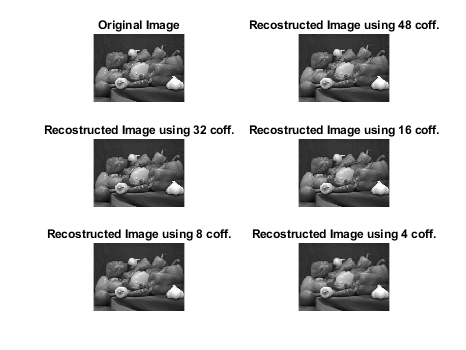

[m,n,n_ch]=size(I);
if n_ch>=2
I=rgb2gray(I);
end
I=double(I);
m1=floor(m/8); m2=m1*8;
n1=floor(n/8); n2=n1*8;  
clear Blocks;
k=0;
coff_48=zeros(1,64);
coff_32=zeros(1,64);
coff_16=zeros(1,64);
coff_8=zeros(1,64);
coff_4=zeros(1,64);
for i = 1:8:m2
for j = 1:8:n2
    k=k+1;
    Blocks=(I(i:i+7,j:j+7));
    dctcoff=dct2(Blocks);
    array=(zigzag(dctcoff))';
    coff_48=zeros(1,64); coff_48(1:48)=array(1:48); 
    Block_48=idct2(izigzag(coff_48,8,8)); I_48(i:i+7,j:j+7)=Block_48;
    coff_32=zeros(1,64); coff_32(1:32)=array(1:32); 
    Block_32=idct2(izigzag(coff_32,8,8)); I_32(i:i+7,j:j+7)=Block_32;
    coff_16=zeros(1,64); coff_16(1:16)=array(1:16); 
    Block_16=idct2(izigzag(coff_16,8,8)); I_16(i:i+7,j:j+7)=Block_16;
    coff_8=zeros(1,64); coff_8(1:8)=array(1:8); 
    Block_8=idct2(izigzag(coff_8,8,8)); I_8(i:i+7,j:j+7)=Block_8;
    coff_4=zeros(1,64); coff_4(1:4)=array(1:4); 
    Block_4=idct2(izigzag(coff_4,8,8)); I_4(i:i+7,j:j+7)=Block_4;
end
end
figure; subplot(321); imshow(uint8(I)); title('Original Image');
subplot(322); imshow(uint8(I_48)); title('Recostructed Image using 48 coff.'); 
subplot(323); imshow(uint8(I_32)); title('Recostructed Image using 32 coff.'); 
subplot(324); imshow(uint8(I_16)); title('Recostructed Image using 16 coff.'); 
subplot(325); imshow(uint8(I_8)); title('Recostructed Image using 8 coff.'); 
subplot(326); imshow(uint8(I_4)); title('Recostructed Image using 4 coff.'); 

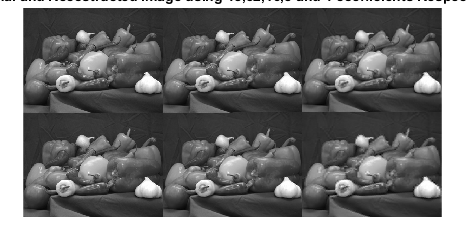

figure; montage({uint8(I),uint8(I_48); uint8(I_32),uint8(I_16); uint8(I_8),uint8(I_4)});
title('Original and Recostructed Image using 48,32,16,8 and 4 coefficients Respectively'); 

(iii) Reconstruct the image with less number of significant coefficients

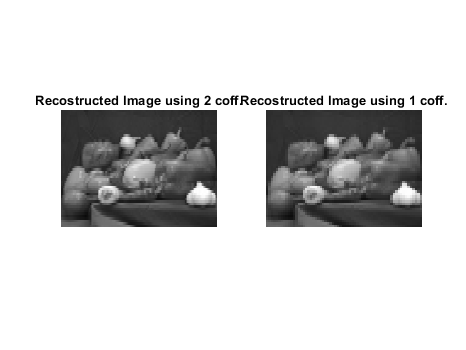

clear Blocks;
k=0;
coff_2=zeros(1,64);
coff_1=zeros(1,64);
for i = 1:8:m2
for j = 1:8:n2
    k=k+1;
    Blocks=(I(i:i+7,j:j+7));
    dctcoff=dct2(Blocks);
    array=(zigzag(dctcoff))';
    coff_2=zeros(1,64); coff_2(1:2)=array(1:2); 
    Block_2=idct2(izigzag(coff_2,8,8)); I_2(i:i+7,j:j+7)=Block_2;
    coff_1=zeros(1,64); coff_1(1:1)=array(1:1); 
    Block_1=idct2(izigzag(coff_1,8,8)); I_1(i:i+7,j:j+7)=Block_1;
end
end
figure; 
subplot(121); imshow(uint8(I_2)); title('Recostructed Image using 2 coff.'); 
subplot(122); imshow(uint8(I_1)); title('Recostructed Image using 1 coff.'); 

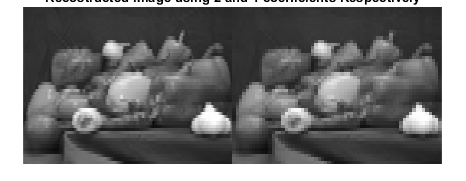


figure; montage({uint8(I_2),uint8(I_1)});
title('Recostructed Image using 2 and 1 coefficients Respectively'); 

5)  Consider an image of sizeN`1×`N`2`

(i) Choose a regoin of interest of sizeM`1×`M`2`within the image.

(ii) Crop the image to display the region of interest.

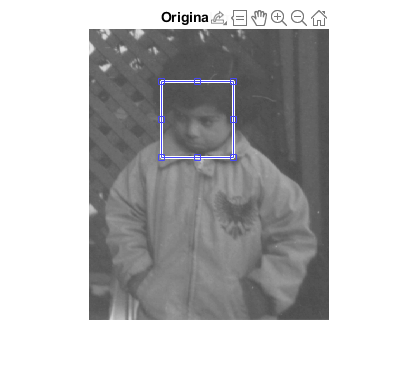

I = imread('pout.tif');
imshow(I); title('Original image'); 
h = imrect; position = wait(h);

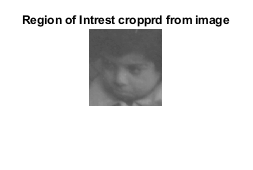

croppedImage = imcrop(I, position);
figure; imshow(croppedImage); title('Region of Intrest cropprd from image'); 